# Планирование движений

2 подзадачи:

Планирование маршрута движения - последоватеельность точек (коордиинат), через которые мы хотим, чтоб манипулятор прошел

Параметризация маршрута по времени

[https://habr.com/ru/post/349044/](https://habr.com/ru/post/349044/) - ссылка на статью по алгоритмам

close all
clear all
clc

Алгоритм жука

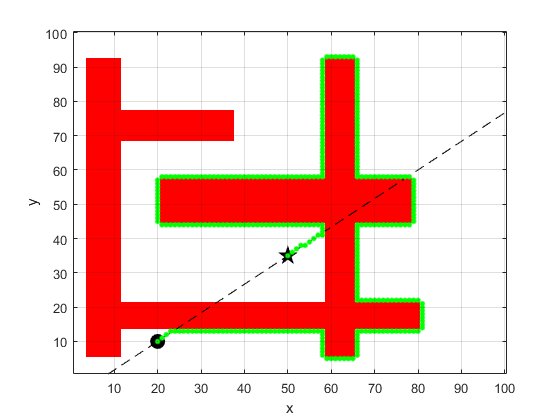

load map1
bug = Bug2(map);
start = [20,10];
goal = [50,35];
bug.query(start, goal, 'animate');

Создание своей карты

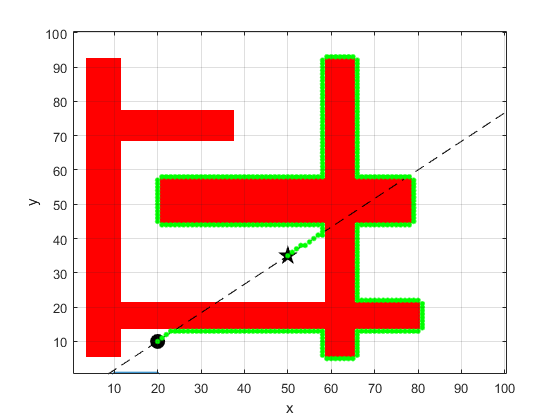

map = zeros(100, 100);
map(10:20) = 1;
plot(map);

Инструкция по созданию карты:

щелчок левой кнопкой мыши и перетаскивание для создания прямоугольника

p нарисовать многоугольник

c нарисовать круг

u отменить последнее действие

e стереть карту

q выйти из режима редактирования и вернуться к карте

% map12 = makemap(100);

Стандратная структура для алгоритмов из супер-класса Navigation

% nav = MyNavClass(world)
% nav.plan()
% nav.plan(goal)
% 
% p = nav.query(start, goal)
% p = nav.query(start)
% nav.plot()
% nav.plot(p)

load house
about house

house [double] : 397x596 (1.9 MB)


place

place = struct with fields:
     kitchen: [320 190]
      garage: [500 150]
         br1: [50 220]
         br2: [120 50]
         br3: [50 50]
        nook: [320 280]
     mudroom: [320 50]
       patio: [200 350]
       study: [220 50]
      garden: [100 350]
    driveway: [500 350]
      living: [220 200]


ds = Dstar(house);
c = ds.costmap();
ds.plan(place.kitchen);
ds.niter
ds.query(place.br3, 'animate');

Смотрим chap5

Задача планирования для манипулятора

https://disk.yandex.ru/d/6UlPB_dndPtoAw

Расчет рабочей зоны манипулятора

close all
clear all
clc
mdl_puma560
N=20;
ki=1;
lim=p560.qlim;
pose=zeros(3,N^3)
% for q1=linspace(-2*pi/3,2*pi/3,N)
  for q1=linspace(lim(1,1),lim(1,2),N)
%     for q2=linspace(-2*pi/3,2*pi/3,N)
    for q2=linspace(lim(2,1),lim(2,2),N)
%         for q3=linspace(-2*pi/3,2*pi/3,N)
          for q3=linspace(lim(3,1),lim(3,2),N)
            q=[q1,q2,q3,0,0,0];
             p0=p560.fkine(q);
             p0=p0.t;
        end
        pose(:,ki)=p0;
        ki=ki+1;
    end
end
line(pose(1,:),pose(2,:),pose(3,:), 'Color',[1 0 0], 'Marker','*')

close all
q1=[0,0,0,0,0,pi];
q2=p560.ikine6s(transl(0.1,0.2,0.2)*trotx(pi/2))
t = [0:0.01:2]';
q = jtraj(q1, q2, t)
[q,qd,qdd] = jtraj(q1, q2, t);
% p560.plot(q)
% plot(t, q(:,2))
% qplot(t, q);
T = p560.fkine(q);
p = transl(T);
% plot(p(:,1), p(:,2))
% plot(t, tr2rpy(T))

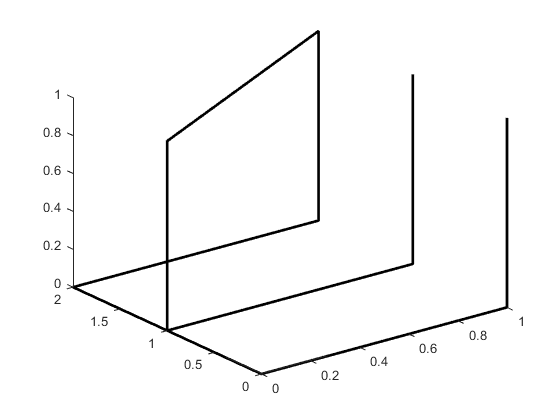


path = [ 1 0 1; 1 0 0; 0 0 0; 0 2 0; 1 2 0;
 1 2 1; 0 1 1; 0 1 0; 1 1 0; 1 1 1];
plot3(path(:,1), path(:,2), path(:,3), 'color', 'k', 'LineWidth', 2)

% матрица точек, ограничения по скорости вдоль осей, начальные координаты,
% шаг по времени, максимальное ускорение
p = mstraj(path, [0.5 0.5 0.3], [], [2 2 2], 0.02, 0.2);
Tp = transl(0.1 * p);
Tp = homtrans( transl(0.4, 0, 0), Tp);
q = irb140.ikine6s(Tp);

смотрим файл spline.m

Simulink манипулятор

sl_jspace

Блоки библиотеки

roblocks